**ECE 101 - Assignment 3 - Arrays and Matricies**

Michael Dekoski

4-17-23

% Clear Workspace/Command Window
clear
clc

Start Timer

startTime = clock();

Matrix 1: 2D Map

% Define matrix size
matrix1Rows = 13;
matrix1Cols = 9;

% Create matrix with all zeros
main2DMatrix = ones(matrix1Rows, matrix1Cols);

% Add ones to the edges to enclose the map
zerosMatrix = zeros(matrix1Rows - 2, matrix1Cols - 2);
main2DMatrix(2:matrix1Rows-1, 2:matrix1Cols-1) = zerosMatrix;

% Add a vertical wall
verticalWall = ones(1,4)';
main2DMatrix(2:5,5) = verticalWall;

% Add a horizontal wall
horizontalWall = ones(1,4);
main2DMatrix(7,5:8) = horizontalWall;

% Add a diagonal wall
main2DMatrix(8:9, 3:4) = rot90(eye(2));

% Place starting and ending points
main2DMatrix(8,8) = 2;
main2DMatrix(3,6) = 3;

main2DMatrix

main2DMatrix =      1     1     1     1     1     1     1     1     1
     1     0     0     0     1     0     0     0     1
     1     0     0     0     1     3     0     0     1
     1     0     0     0     1     0     0     0     1
     1     0     0     0     1     0     0     0     1
     1     0     0     0     0     0     0     0     1
     1     0     0     0     1     1     1     1     1
     1     0     0     1     0     0     0     2     1
     1     0     1     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     1


Matrix 2: Topological Map of Upper Peninsula Snowfall for the 21-22 Winter Season

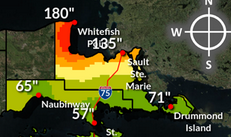

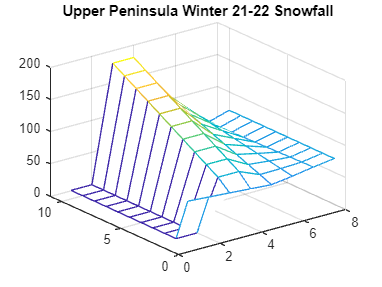

% Define matrix size
matrix2Rows = 11;
matrix2Cols = 8;

% Define high and low points
highPoint = 180;    % in inches
lowPoint = 57;       % in inches

% Define other points
secondHigh = highPoint - lowPoint;  % in inches (123in)
secondLow = lowPoint + (lowPoint/6);    % in inches (66.5in)
middlePoint = lowPoint + (lowPoint/4);  % in inches (71.25in)

% Create matrix with linspace function
% Base Array as zeros
topologicalMatrix = zeros(matrix2Rows,matrix2Cols);

% Highest point to second lowest
topologicalMatrix(1:11, 3) = linspace(secondLow,...
                highPoint,11)';
topologicalMatrix(1:11, 4) = linspace(secondLow,...
                highPoint,11)';

% Second lowest to lowest point
topologicalMatrix(1, 1:5) = linspace(secondLow,...
                lowPoint, 5);

% Lowest point to middle point
topologicalMatrix(1, 5:8) = linspace(lowPoint,...
                middlePoint, 4);

% Second highest point to middle point
topologicalMatrix(10, 5:8) = linspace(secondHigh,...
                middlePoint, 4);

% Highest point to second highest point
topologicalMatrix(11, 4:5) = linspace(highPoint,...
                secondHigh, 2);

% Lowest point to second highest point
topologicalMatrix(1:10, 5) = linspace(lowPoint,...
                secondHigh, 10)';

% Transition from space between second highest and middle points
topologicalMatrix(1:10, 6) = linspace(...
                lowPoint+(middlePoint/16),...
                secondHigh-(secondHigh/4), 10)';
topologicalMatrix(1:10, 7) = linspace(...
                middlePoint-(middlePoint/16),...
                secondHigh-(secondHigh/2), 10)';
topologicalMatrix(1:10, 8) = linspace(middlePoint, middlePoint, 10)';

% Display matrix
figure(1)
mesh(topologicalMatrix)
title('Upper Peninsula Winter 21-22 Snowfall')

End Timer

% End time
stopTime = clock();

Calculate elapsed time

% vector into seconds
startSec = startTime(6) + (startTime(5)*60) + (startTime(4)*3600);

stopSec = stopTime(6) + (stopTime(5)*60) + (stopTime(4)*3600);

dayDiff = stopTime(3) - startTime(3);

dayInSec = dayDiff * 86400;

timeInHours = (stopSec - startSec + dayInSec)/3600;

hour = floor(timeInHours)

hour = 16


hourRem = timeInHours - hour;

timeInMinutes = hourRem * 60;

min = floor(timeInMinutes)

min = 4


minRem = timeInMinutes - min;

sec = minRem * 60

sec = 37.7980